
t = tiledlayout(1,2);

nexttile
msh = generateMesh(smodel1, 'Hmax', 0.05);
Rs1 = solve(smodel1);
subplot(1,2,1);
pdeplot3D(smodel1, 'ColorMapData', Rs1.VonMisesStress, 'Deformation', Rs1.Displacement, 'DeformationScaleFactor', 100);
title('Mesh size = 0.05');

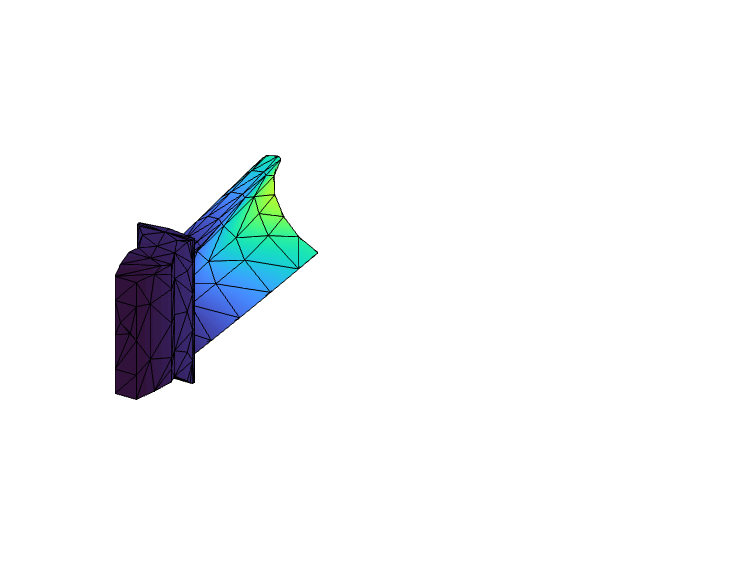

% Data to visualize
meshData = Rs1.Mesh;
nodalData = Rs1.Displacement.Magnitude;
deformationData = Rs1.Displacement;

% Create PDE result visualization
resultViz2 = pdeviz(meshData,abs(real(nodalData)), ...
    "DeformationData",deformationData, ...
    "DeformationScaleFactor",0, ...
    "AxesVisible",false, ...
    "ColorbarVisible",false, ...
    "MeshVisible",true, ...
    "Title","Magnitude displacement", ...
    "ColorLimits",[0 0.00022]);


% Clear temporary variables
clearvars meshData nodalData deformationData




%nexttile
msh = generateMesh(smodel3, 'Hmax', 0.0125);

Unrecognized function or variable 'smodel3'.

Rs3 = solve(smodel3);
subplot(1,2,2)
pdeplot3D(smodel3, 'ColorMapData', Rs3.VonMisesStress, 'Deformation', Rs3.Displacement, 'DeformationScaleFactor', 100);
title('Mesh size = 0.0125');

% Data to visualize
meshData3 = Rs3.Mesh;
nodalData3 = Rs3.Displacement.Magnitude;
deformationData3 = Rs3.Displacement;

% Create PDE result visualization
resultViz4 = pdeviz(meshData3,abs(real(nodalData3)), ...
    "DeformationData",deformationData3, ...
    "DeformationScaleFactor",0, ...
    "AxesVisible",false, ...
    "MeshVisible",true, ...
    "Title","Magnitude displacement", ...
    "ColorLimits",[0 0.00022]);

% Clear temporary variables
clearvars meshData3 nodalData3 deformationData3

cH = colorbar;
set(cH,'FontSize',30);
